% Caleb Distel | SES 598
% 10/29/2025
% Chirp Radar matlab activity
clear; clc; close all;

Fs  = 60e6;
T   = 20e-6; % chirp duration
t   = 0:1/Fs:T-1/Fs;
f1  = 10e6; f2 = 20e6;
fLO = 15e6; % mix for diff: -5...5; sum: 25...35
M   = 2; % Decimate by 2 Fs -> Fs2 = 60MHz -> 30MHz
Nfft = 8192;
f_xlim = [-40 40];
% Next: mix -> LPF -> decimate

## Build signal and mix LO

x     = chirp(t, f1, T, f2, 'linear'); % sweep 10 -> 20 MHz
lo    = cos(2 *pi*fLO*t); % 15 MHz LO
y_mix = x .* lo;

## LPF to satisfy new nyquist for Fs2 (30MHz) -> Low Pass filter to accept < 15MHz

N = 96; Fc = 8e6; % anti-alias LPF to keep -5...5 MHz
b = fir1(N, Fc/(Fs/2)); % Hamming LPF
y_lp = filter(b, 1, y_mix); % filtered signal

## Decimate with M = 2 to drop every other sample (Fs -> Fs2)

y_ds = y_lp(1:M:end); % downsample by 2
Fs2  = Fs/M;          % Fs -> Fs2 (60 MHz -> 30MHz)

## Helper: spectrum in MHz (Hann window, dB)

spec = @(sig,Fsamp) deal( ...
    linspace(-Fsamp/2, Fsamp/2, Nfft)/1e6, ...
    20 * log10(abs(fftshift(fft((sig(:).*hann(numel(sig))).', Nfft))) + 1e-12));

## Stage Spectra

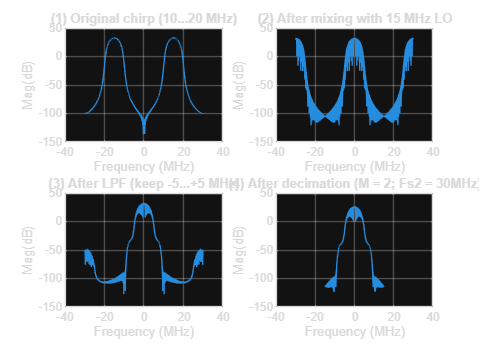

[fx, XdB] = spec(x,     Fs);  % original signal
[fm, MdB] = spec(y_mix, Fs);  % mixed signal (x + LO)
[ff, LdB] = spec(y_lp,  Fs);  % Filtered signal -> mixed[ f < 15MHz ]
[fd, DdB] = spec(y_ds,  Fs2); % Decimated signal -> filtered @ 30MHz (Fs2)

figure('Color', 'w', 'Position', [70 70 1020 740]);
subplot(2,2,1); plot(fx, XdB); grid on; xlim(f_xlim);
title('(1) Original chirp (10...20 MHz)'); xlabel('Frequency (MHz)'); ylabel('Mag(dB)');

subplot(2,2,2); plot(fm, MdB); grid on; xlim(f_xlim);
title('(2) After mixing with 15 MHz LO'); xlabel('Frequency (MHz)'); ylabel('Mag(dB)');

subplot(2,2,3); plot(ff, LdB); grid on; xlim(f_xlim);
title('(3) After LPF (keep -5...+5 MHz)'); xlabel('Frequency (MHz)'); ylabel('Mag(dB)');

subplot(2,2,4); plot(fd, DdB); grid on; xlim(f_xlim);
title('(4) After decimation (M = 2; Fs2 = 30MHz)'); xlabel('Frequency (MHz)'); ylabel('Mag(dB)');

## Compare on original-Fs (60MHz) axis (-10...+10 MHz)

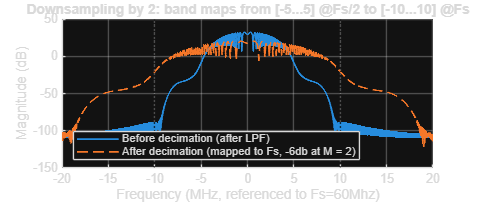

[ff0, Ypre_dB]  = spec(y_lp, Fs);  % Pre-decimation (Fs)
[fd2, Ypost_dB] = spec(y_ds, Fs2); % Post-decimation (Fs2)

fd2_on_Fs      = fd2 * M;      % Map to original Fs (*M)
Ypost_on_Fs_dB = Ypost_dB - 6; % amplitude is half -> ~-6 dB

figure('Color', 'w', 'Position', [120 120 900 380]);
hold on; grid on; 
plot(ff0, Ypre_dB, 'Linewidth', 1.2);
plot(fd2_on_Fs, Ypost_on_Fs_dB, '--', 'Linewidth', 1.2);
xline([-10 10], ':k');
xlim([-20 20]); xlabel('Frequency (MHz, referenced to Fs=60Mhz)');
ylabel('Magnitude (dB)');
title('Downsampling by 2: band maps from [-5...5] @Fs/2 to [-10...10] @Fs');
legend('Before decimation (after LPF)', 'After decimation (mapped to Fs, -6db at M = 2)', 'Location', 'SouthWest');